# `Script to Plot Multiple Datasets on One Plot`

Read in JSON File for plotting configuration, specify base path

clf
clear

david_file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/";
windows_file_path = "C:\Users\Operator\Documents\RadarSecurityResearch\MATLAB\Simulink Model\";
kristen_file_path = "/home/kristenangell/Documents/RadarSecurityResearch/MATLAB/Simulink Model/";

base_path = kristen_file_path;

json_text = fileread(base_path + "config_files/" + "test_config.json");
sim_config = jsondecode(json_text);
json_text_plot = fileread(base_path + "config_files/" + "plot_config.json");
plot_config = jsondecode(json_text_plot);

Specify desired title

desired_title = "P(detection) for 1GHz at Various Target Ranges";

Automatically set up JSON configurations

plot_p_detection = plot_config.PlotSettings.Configurations.plot_p_detection;
plot_p_false_pos = plot_config.PlotSettings.Configurations.plot_p_false_pos;
NUM_RUNS = sim_config.TestSettings.Configurations.num_runs;
FRAMES_PER_RUN = sim_config.TestSettings.Configurations.frames_per_sim;
PRE_ATTACK_FRAMES = sim_config.TestSettings.Configurations.pre_attack_frames;
MAX_BIN = plot_config.PlotSettings.Configurations.max_bin;
BIN_WIDTH = plot_config.PlotSettings.Configurations.bin_width;

TOTAL_FRAMES = NUM_RUNS * (FRAMES_PER_RUN-PRE_ATTACK_FRAMES);

Specify CSVs to 

csvs = ["1GHzNoAttack.csv", "1GHzSimilarSlopeAndVelocity.csv"];
% csvs = ["4GHz_no_attack.csv", "4GHz_sim_slope_noisy_vel.csv",...
%     "4GHz_target.csv","4GHz_sim_slope_sim_vel.csv"];
% csvs = ["20MHz_sim_slope_noisy_vel.csv", "100MHz_sim_slope_noisy_vel.csv",...
%     "1GHz_sim_slope_noisy_vel.csv","4GHz_sim_slope_noisy_vel.csv"];

colors_list = ["b", "g", "c", "m", "y", "k", "r"];
color_idx = 1;

for csv = csvs
    table_data = readtable(base_path + "csvs_to_plot/" + csv);
    range_col = table_data{:, 1};
    bin_classification = cast(range_col/BIN_WIDTH, "int16")';
    histogram_vals = zeros(MAX_BIN,3);
    for bin_num = 1:MAX_BIN
        histogram_vals(bin_num, 1) = bin_num;
        count = 0;
        detected = 0;
        false_pos = 0;
        for frame = 1: TOTAL_FRAMES
            if (bin_classification(frame) == bin_num)
                count = count + 1;
                if table_data{frame, 3}
                    detected = detected + 1;
                end
                if table_data{frame, 8}
                    false_pos = false_pos + 1;
                end
            end
        end
        if (count ~= 0)
            histogram_vals(bin_num, 2) = detected/count;
            histogram_vals(bin_num, 3) = false_pos/count;
        end
    end

    if (plot_p_detection)
        hold on
        plot(histogram_vals(:,1)*BIN_WIDTH, histogram_vals(:,2), colors_list(color_idx));
        color_idx = color_idx +1;
        hold off
    end

    if (plot_p_false_pos)
        hold on
        plot(histogram_vals(:,1)*BIN_WIDTH, histogram_vals(:,3), colors_list(color_idx));
        color_idx = color_idx + 1;
        hold off
    end
end

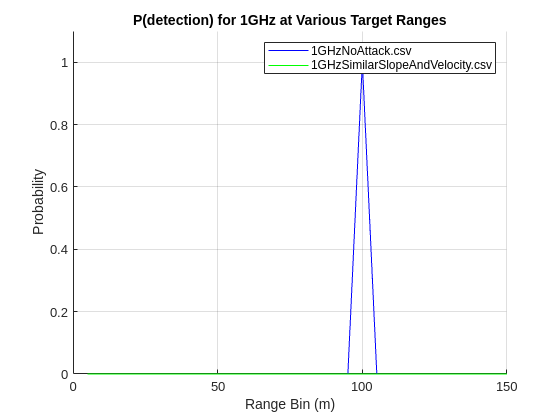

ylabel("Probability")
ylim([0,1.1])
legend(csvs)
xlabel("Range Bin (m)")
title(desired_title)
grid()
print('-r300',"generated_plots/combined_result_plot",'-dsvg')
print('-r300',"generated_plots/combined_result_plot",'-dpng')